% Step 1
% Mean Gaussian = 0
% Variance Gaussian = sigma^2

mu = 0;
sigma = sqrt(2);
M = 100;

data = normrnd(mu, sigma, 1, M);

disp('Random Gaussian Distribution:');

Random Gaussian Distribution:


disp(data);

    1.2312    0.4678   -1.9062    2.1890   -0.8721   -0.9879   -2.0133   -0.1550   -0.1453   -0.4564   -1.1874   -2.3484    4.2603    2.1225   -0.5077   -0.1625    0.5076   -0.0172   -0.8066    1.3209   -1.6098    2.7680   -2.4936   -0.4573    1.2340    0.1668   -2.1256    1.3037    0.2309   -1.1521    0.5709    1.0694    3.0893   -0.1326   -0.4161   -0.7139   -2.7252    0.7373   -2.9054   -0.3816   -0.3890    1.1952   -3.9190    1.2984   -0.7343   -1.8286   -0.0123    0.3300   -0.5999   -2.0781    1.7061    0.2791   -0.9997    1.7202    0.5193   -1.7925    0.8783   -2.5392   -1.4960    0.2143    0.5816    0.0997   -2.7337    1.1578    1.7844    1.6509   -0.8066   -0.5571   -1.4389    0.3538    0.3566   -1.0910    1.3004    1.2051    0.9293   -1.0656   -1.8929    0.9224    2.0467   -1.8245   -3.1229    2.0310   -0.0872    1.6657    1.3937   -1.7233   -0.6108   -1.1808    0.2541    1.6494    0.0792   -2.9699    1.7470    0.0038   -0.6499   -2.9743    0.5288    0.3467    0.4788   -1.5246

% Step 2

mu_s = mean(data);      % Sample Mean of Data
sigma_s = std(data);    % Sample Standard Deviation of Data

disp(['Sample Mean: ', num2str(mu_s)]);

Sample Mean: -0.15344


disp(['Sample Standard Deviation: ', num2str(sigma_s)]);

Sample Standard Deviation: 1.5392


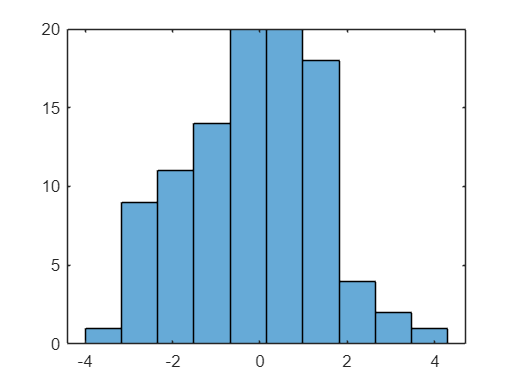

% Step 3

K = 10;
h = histogram(data, K);

mj = h.Values;                                  % # Samples In Each Bin
Cj = h.BinEdges(1:end-1) + diff(h.BinEdges)/2;  % Centers Of Each Bin

disp('Bin Samples (mj):');

Bin Samples (mj):


disp(mj);

     1     9    11    14    20    20    18     4     2     1



disp('Bin Centers (Cj):');

Bin Centers (Cj):


disp(Cj);

   -3.5850   -2.7550   -1.9250   -1.0950   -0.2650    0.5650    1.3950    2.2250    3.0550    3.8850



% Step 4

Delta = (Cj(end) - Cj(1)) / (K - 1);    % (End Bin - Start Bin) / # Gaps

disp(['Bin Length Delta: ', num2str(Delta)]);

Bin Length Delta: 0.83


% Step 5

simulated_pdf = mj / (M * Delta);   % Directly From Lab Procedure

disp('Simulated pdf at Bin Centers:');

Simulated pdf at Bin Centers:


disp(simulated_pdf);

    0.0120    0.1084    0.1325    0.1687    0.2410    0.2410    0.2169    0.0482    0.0241    0.0120



% Step 6

numerator = -((Cj - mu_s).^2);          % Numerator
denominator = 2 * sigma_s^2;            % Denominator
scalar = 1 / (sigma_s * sqrt(2*pi));    % Scalar / Front Value?

theoretical_pdf = scalar * exp(numerator / denominator);

disp('Theoretical pdf at Bin Centers:');

Theoretical pdf at Bin Centers:


disp(simulated_pdf);

    0.0120    0.1084    0.1325    0.1687    0.2410    0.2410    0.2169    0.0482    0.0241    0.0120



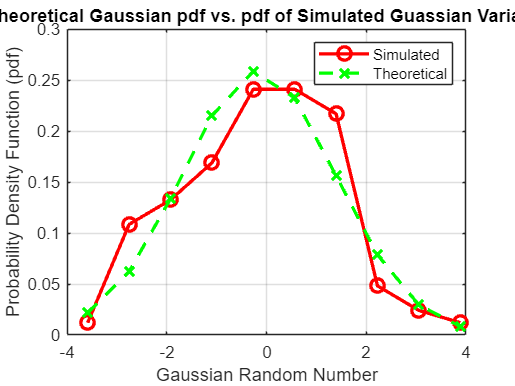

% Step 7

figure;
plot(Cj, simulated_pdf, 'r-o', 'LineWidth', 2, 'MarkerSize', 8);
hold on;

plot(Cj, theoretical_pdf, 'g-x', 'LineStyle', '--', 'LineWidth', 2, 'MarkerSize', 8);

xlabel('Gaussian Random Number');
ylabel('Probability Density Function (pdf)');
title('Theoretical Gaussian pdf vs. pdf of Simulated Guassian Variates');
legend('Simulated', 'Theoretical');

grid on;
hold off;